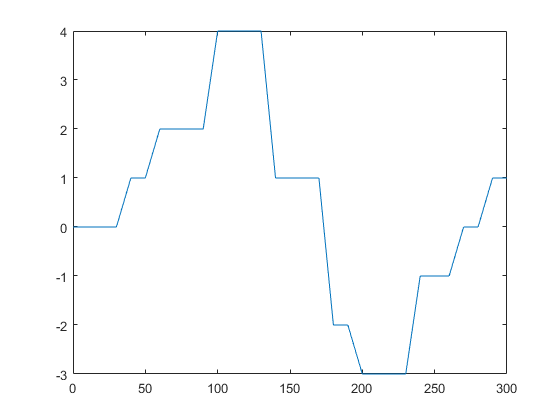

pulsewidth = 10;
chirp_gain = 1;
chirp_fo = 1;
chirp_mu = 1;
chirp_delta_tau = 0;
dt = 0.01;
c = 3*10^8;
R = 20000;

ground = [0 0 0 0 1 1 2 2 2 2 4 4 4 4 1 1 1 1 -2 -2 -3 -3 -3 -3 -1 -1 -1 0 0 1 1];
x = 0 : 10 : 300;
plot(x,ground);

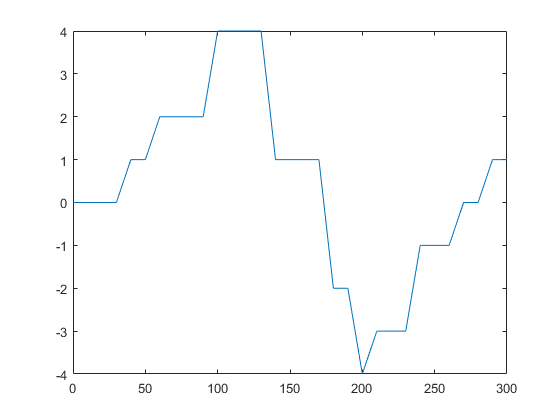


% 거리측정 
new_ground = R + ground;                    % [m]
time = (2*new_ground/c)*10^9;               % [ns]
time_with_noise = time + 2*randn(1,31);
R_with_noise = (time_with_noise*c/2)*10^-9;
ground_with_noise = R_with_noise - R;
final_ground = round(ground_with_noise);    % 최종 ground input data
plot(x,final_ground);

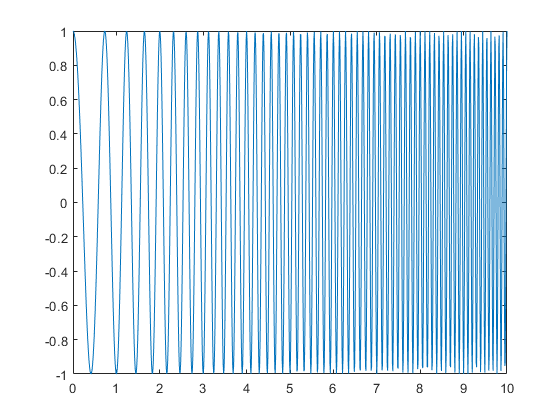


% signal
t = 0 : pulsewidth*10^-3 : pulsewidth;      % 0 : 0.01 : 10 [ns]
N_t = 0 : pulsewidth*10^-1 : pulsewidth;    % 0 : 1 : 10
N = length(t);
st1 = chirp_gain.*cos(2*pi.*(chirp_fo*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
plot(t,st1);

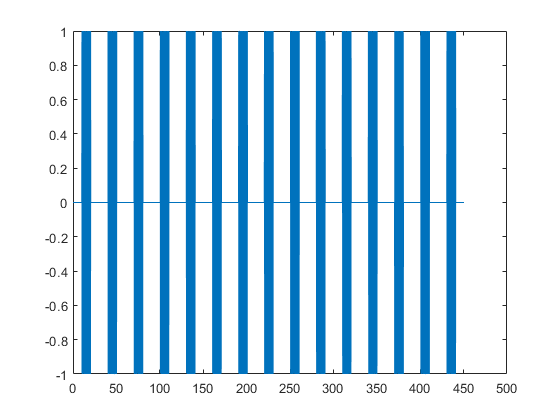

st2 = chirp_gain.*cos(2*pi.*(2*(t - chirp_delta_tau) + (1/2).*(t - chirp_delta_tau).^2));
st3 = chirp_gain.*cos(2*pi.*(3*(t - 0.5) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
st4 = chirp_gain.*cos(2*pi.*(4*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
st5 = chirp_gain.*cos(2*pi.*(5*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
st6 = chirp_gain.*cos(2*pi.*(6*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
st7 = chirp_gain.*cos(2*pi.*(7*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
st8 = chirp_gain.*cos(2*pi.*(8*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
            
rt1 = [ zeros(1,N), st1, zeros(1,N) ];
rt2 = [ zeros(1,N+10), st2, zeros(1,N-10) ];
rt3 = [ zeros(1,N+20), st3, zeros(1,N-20) ];
rt4 = [ zeros(1,N+30), st4, zeros(1,N-30) ];
rt5 = [ zeros(1,N+40), st5, zeros(1,N-40) ];
rt6 = [ zeros(1,N+50), st6, zeros(1,N-50) ];
rt7 = [ zeros(1,N+60), st7, zeros(1,N-60) ];
rt8 = [ zeros(1,N+70), st8, zeros(1,N-70) ];

% received signal
rt = (rt4+rt4+rt5+rt6+rt6+rt8+rt8+rt5+rt5+rt2+rt1+rt1+rt3+rt4+rt5); %+randn(1,length(rt4+rt4+rt5+rt6+rt6+rt8+rt8+rt5+rt5+rt2+rt1+rt1+rt3+rt4+rt5));
rt_matrix = [rt4, rt4, rt5, rt6, rt6, rt8, rt8, rt5, rt5, rt2, rt1, rt1, rt3, rt4, rt5];
plot((0:45*length(t)-1)*dt,rt_matrix);

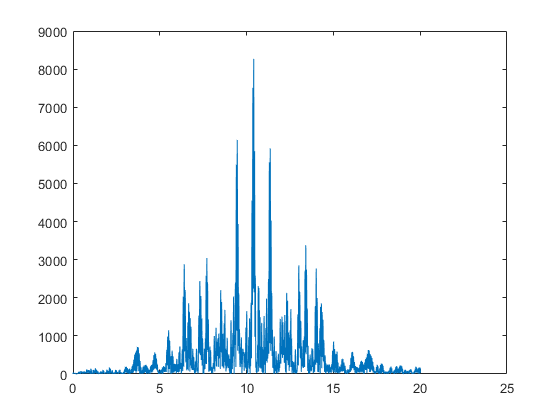


% correlation processor 
ct = length(rt)-N;
    for a = 0:ct
        c(a+1) = rt(a+1:a+N)*(st4+st4+st5+st6+st6+st8+st8+st5+st5+st2+st1+st1+st3+st4+st5)';
    end

plot((0:length(c)-1)*dt, abs(c));